# Gene expression part 05

## © 2017 Griffin Chure & Manuel Razo. This work is licensed under a [Creative Commons Attribution License CC-BY 4.0](https://creativecommons.org/licenses/by/4.0/). All code contained herein is licensed under an [MIT license](https://opensource.org/licenses/MIT)

In this final part of our analysis we will use the single cell measurements generated in the previous section to compute the experimental fold-change. As we saw when performing the experiment the way we compute the experimental fold-change is given by


$$\text{fold-change} = {\langle \text{YFP}(R > 0) \rangle - \langle \text{auto} \rangle \over \langle \text{YFP}(R = 0) \rangle - \langle \text{auto} \rangle},$$


where $\langle \text{YFP}(R > 0) \rangle$is the mean YFP fluorescent value of a strain with certain number of repressors, $\langle \text{auto} \rangle$is the mean autofluorescent value and $\langle \text{YFP}(R = 0)\rangle$is the mean YFP level of the Delta strain.

To compute this quantity let's first read load the single-cell measurements along with the list of directories from which these measurements came.

% Define directory containing the data
dataDir = '/Volumes/razo_data/MBL/2017/PBoC/20170812_2/';

% load single cell measurements
% load('data/lacI_titration/single_cell_fluorescence.mat')
load([dataDir,'single_cell_fluorescence.mat'])

% list all the files inside the lacI_titration directory
dirObjects = dir(dataDir);
% find the directories for each of the strains
dirIdx = [dirObjects.isdir]; % list the index of dir objects
dirObjects = dirObjects(dirIdx); % find the directories
% Loop through each of the directories making sure the length of the name
% makes sense given how we named the files. This is to avoid havin the './' and
% '../' directories listed
strainDirs = {}; % initialize empty cell to save directory names
for i=1:length(dirObjects)
    if length(dirObjects(i).name) > 2
        strainDirs{end+1} = dirObjects(i).name;
    end %if
end %for

There is a one-to-one mapping between the entries in `strainDirs` and `fluorValues`. We can use this to find index each of the strains

% find the corresponding single-cell measurements of: auto
auto = fluorValues(strcmp(strainDirs, 'auto'));
% compute the mean autofluorescence
meanAuto = mean(auto{1});

% find the corresponding single-cell measurements of: auto
delta = fluorValues(strcmp(strainDirs, 'delta'));
% compute the mean autofluorescence
meanDelta = mean(delta{1});

% initialize array to save fold-change
foldChange = [];
% Compute the fold-change for each of the strains
for i=1:length(strainDirs)
    foldChange(end+1) = (mean(fluorValues{i}) - meanAuto) / (meanDelta - meanAuto);
end %for

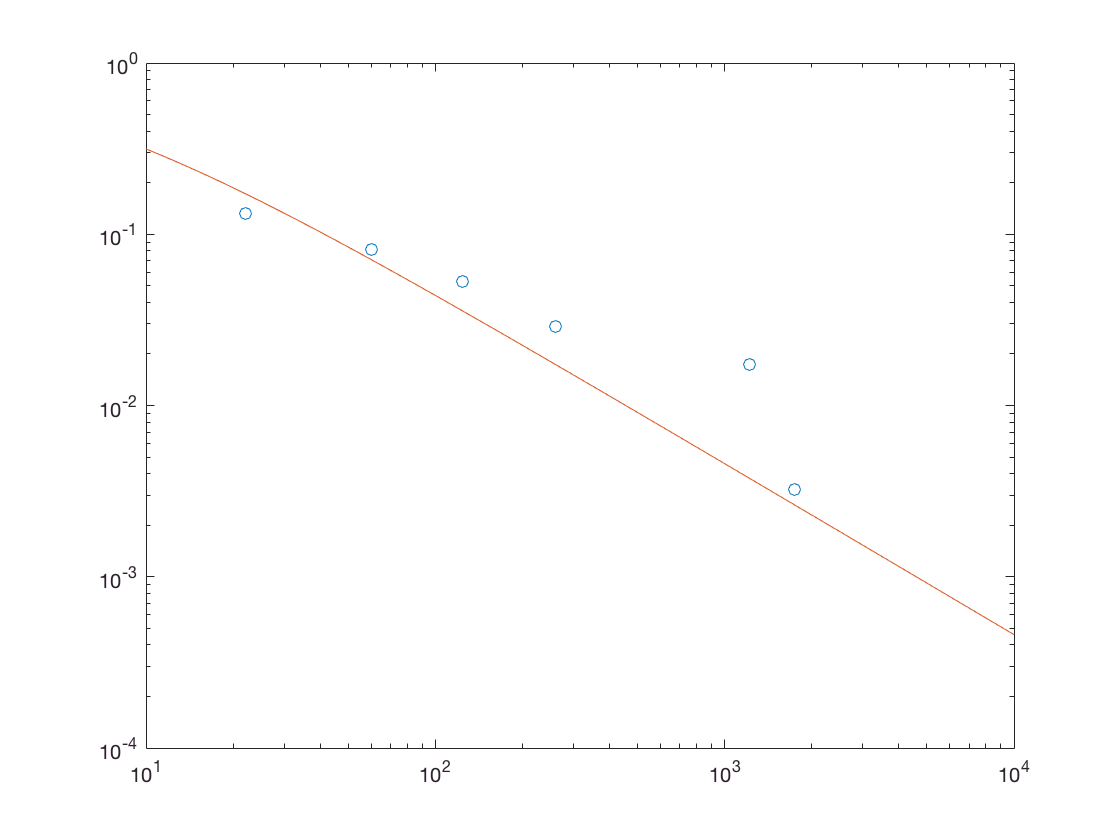

% repressors = [0, 0, 22, 60, 124, 260, 1220, 1740];
repressors = [1220, 124, 1740, 22, 260, 60, 0, 0];
loglog(repressors, foldChange, 'o')
hold on
repArray = logspace(1, 4, 100);
fcTheory = 1 ./ (1 + repArray ./ 5E6 .* exp(13.9));
loglog(repArray, fcTheory)
hold off